# Task 1

A= [0 0 0 0 0 0];
B=[0 0 1 0 pi/2 0];
C=[1 0 1 0 -pi 0];
D=[1 0 -0.5 0 pi/2 0];
x=[A(1) B(1) C(1) D(1)];

x =      0     0     1     1


y=[A(2) B(2) C(2) D(2)];

y =      0     0     0     0


z=[A(3) B(3) C(3) D(3)];

z =          0    1.0000    1.0000   -0.5000


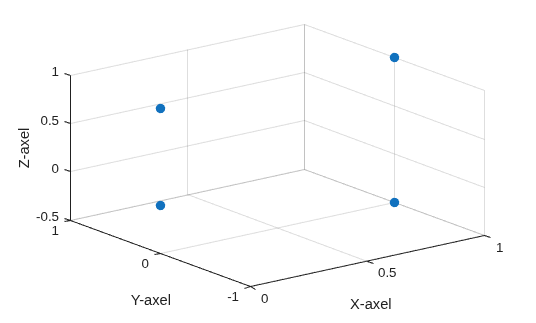

scatter3(x, y, z, 50, 'filled'); % '50' är storleken på prickarna
grid on;
xlabel('X-axel');
ylabel('Y-axel');
zlabel('Z-axel');

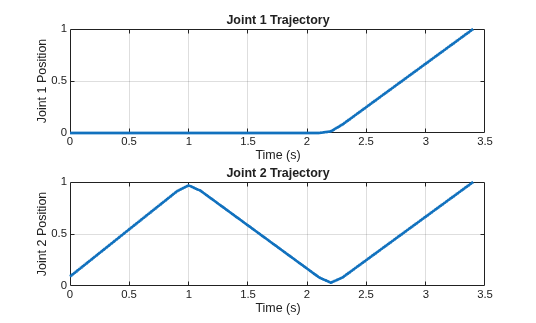

via = [ B(1) C(1) D(1)
        B(2) C(2) D(2)
        B(3) C(3) D(3)];
qdmax = [1 1 1];
q0 = A(1:3);

% Sampling time
dt = 0.1;

% Acceleration time
tacc = 0.2;

% Generate trajectory
q = mstraj(via, qdmax, [], q0, dt, tacc);

% Generate time vector
t = (0:size(q,1)-1)*dt;

% Plot trajectory
figure;

subplot(2,1,1);
plot(t, q(:,1), 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Joint 1 Position');
title('Joint 1 Trajectory');

subplot(2,1,2);
plot(t, q(:,2), 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Joint 2 Position');
title('Joint 2 Trajectory');